# PIVLab  commandline data analysis workflow

## Create PIVLab image analysis options

pv = pivlab.options();
pv.pairWise = true;
% pv.roi = [5, 150, 300, 200];

## Perform PIV Image analysis

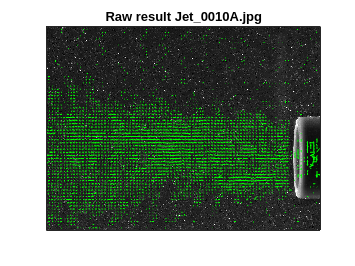

[x,y,u,v,tv,cm] = pivImageAnalysis("Examples/Jet*.jpg",pv);

## Create velocity filering options

pv = pivlab.VelocityFileringOptions();
[xfil, yfil, tvfil] = pivVelocityFilter(u,v,tv,pv);